# Use Custom Scheduler in 5G System-Level Simulation

This example shows how to create a custom resource-scheduling strategy, using the [`nrScheduler`](docid:5g_ref#mw_56dd154e-95de-4db5-be86-dfdd6ede2dcb) class, and use it in a 5G system-level simulation. When developing a custom scheduling strategy, you can:

- Use the available properties from the [`nrScheduler`](docid:5g_ref#mw_56dd154e-95de-4db5-be86-dfdd6ede2dcb) class.

- Define custom user equipment (UE) information and use it in the scheduling strategy.

- Define custom properties and methods in the scheduling strategy.

- Define custom statistics for your scheduling strategy.

This example features various simulation logs and visualizations that you can use to assess the impact of the developed scheduling strategy on network performance. This figure indicates where a scheduler resides in the protocol stack along with its customization.

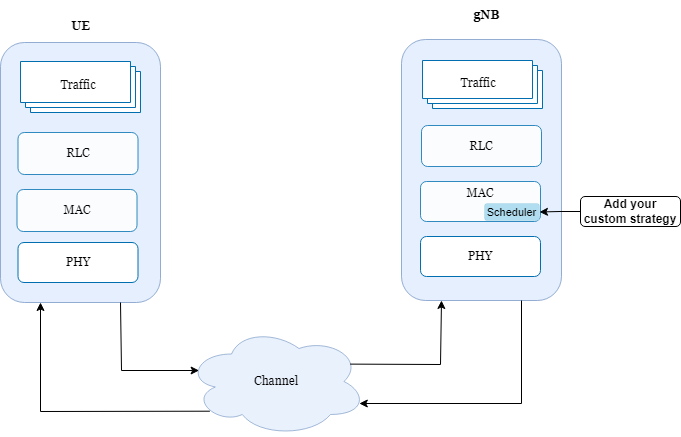

## `nrScheduler` Class

The [`nrScheduler`](docid:5g_ref#mw_56dd154e-95de-4db5-be86-dfdd6ede2dcb) class handles physical uplink shared channel (PUSCH) and physical downlink shared channel (PDSCH) resource scheduling. For each scheduled slot, the class prioritizes satisfying the retransmission requirements of the UE nodes. After addressing retransmissions, it schedules new transmissions with the remaining frequency resources within the bandwidth. You can customize the new transmission scheduling by creating a subclass of [`nrScheduler`](docid:5g_ref#mw_56dd154e-95de-4db5-be86-dfdd6ede2dcb) and writing your custom scheduling logic. 

The [`nrScheduler`](docid:5g_ref#mw_56dd154e-95de-4db5-be86-dfdd6ede2dcb) class provides access to various information, such as UE buffer status, channel quality, and other relevant details, through its properties. You can use these properties to write an intelligent scheduling strategy. The [`nrScheduler`](docid:5g_ref#mw_56dd154e-95de-4db5-be86-dfdd6ede2dcb) class exposes [`scheduleNewTransmissionDL`](docid:5g_ref#mw_60c8f75a-8de3-47bb-bd6f-d4ba51256741) and [`scheduleNewTransmissionUL`](docid:5g_ref#mw_dcab66e3-229f-4f08-89b1-3de7edf99d52) as protected methods, enabling you to override them in your custom strategy class inherited from [`nrScheduler`](docid:5g_ref#mw_56dd154e-95de-4db5-be86-dfdd6ede2dcb).

## Write Custom Scheduling Strategy

This example uses the scheduling strategy implemented in the helper file [`helperNRCustomSchedulingStrategy`](matlab:openExample('5g/NRPlugCustomSchedulerExample','supportingFile','helperNRCustomSchedulingStrategy')), which inherits from [`nrScheduler`](docid:5g_ref#mw_56dd154e-95de-4db5-be86-dfdd6ede2dcb).

### Strategy Description

The scheduling strategy in this example allocates resource blocks (RBs) to UE nodes based on their priorities. At setup, you can categorize each UE node as either high-priority (priority 1) or low-priority (priority 2). During runtime, the scheduling strategy executes these steps in each scheduled slot:

- Scheduling of High-Priority UE nodes—The strategy allots a predefined, fixed number of RBs to each eligible high-priority UE. For more information about eligible UE nodes, see the [`scheduleNewTransmissionDL`](docid:5g_ref#mw_60c8f75a-8de3-47bb-bd6f-d4ba51256741) and [`scheduleNewTransmissionUL`](docid:5g_ref#mw_dcab66e3-229f-4f08-89b1-3de7edf99d52) methods of the [`nrScheduler`](docid:5g_ref#mw_56dd154e-95de-4db5-be86-dfdd6ede2dcb) class. If the strategy cannot serve all high-priority UE nodes with the required fixed number of RBs, then it schedules UE nodes from a randomly selected subset of high-priority UE nodes in the slot.

- Scheduling of Low-Priority UE nodes— After allocating RBs to high-priority UE nodes, if any RBs remain free, the scheduling strategy distributes them equally among the low-priority UE nodes.

This strategy applies to both downlink (DL) and uplink (UL) new transmission scheduling. You can implement different logic for DL and UL scheduling in your custom strategy.

## Plug Custom Scheduling Strategy into Simulation

Create a 5G system-level simulation scenario and add the custom scheduling strategy to it.

Check if the Communications Toolbox™ Wireless Network Simulation Library support package is installed. If the support package is not installed, MATLAB® returns an error with a link to download and install the support package.

wirelessnetworkSupportPackageCheck

Create a wireless network simulator.

rng("default")           % Reset the random number generator
numFrameSimulation = 30; % Simulation time in terms of number of 10 ms frames
networkSimulator = wirelessNetworkSimulator.init;

Create a gNB node and specify its position, carrier frequency, channel bandwidth, subcarrier spacing, receive gain, number of transmit and receive antennas, and sounding reference signal (SRS) transmission periodicity (in slots) for all connecting UE nodes.

gNB = nrGNB(Position=[0 0 10],CarrierFrequency=2.6e9,ChannelBandwidth=5e6,SubcarrierSpacing=15e3,ReceiveGain=11, ...
   NumTransmitAntennas=16,NumReceiveAntennas=8,SRSPeriodicityUE=40);

Create an object of the custom scheduler class [`helperNRCustomSchedulingStrategy`](matlab:openExample('5g/NRPlugCustomSchedulerExample','supportingFile','helperNRCustomSchedulingStrategy')). Specify the fixed number of RBs allocated to a high-priority UE in a DL assignment or a UL grant by using the `NumRBHighPriority` property of the object. If the number of free RBs is less than this number, then the scheduler allocates all the free RBs to a randomly selected high-priority UE node. After creating the custom scheduler object, add it to the gNB node.

myScheduler = helperNRCustomSchedulingStrategy(NumRBHighPriority=4);
configureScheduler(gNB,Scheduler=myScheduler);

Create four UE nodes. Specify the name and the position of each UE node.

numUEs = 4;
uePositions = [randi([0 250],numUEs,2) ones(numUEs,1)];
ueNames = "UE-" + (1:size(uePositions,1));
UEs = nrUE(Name=ueNames,Position=uePositions);

Connect the UE nodes to the gNB node, set the DL channel state information (CSI) report periodicity to 10 slots, and assign the custom UE context named `Priority` to each UE node. Divide the nodes into high-priority and low-priority groups, with the half designated as high priority and the other half as low priority. The custom scheduling strategy [`helperNRCustomSchedulingStrategy`](matlab:openExample('5g/NRPlugCustomSchedulerExample','supportingFile','helperNRCustomSchedulingStrategy')) uses this configuration during resource scheduling. For more information about how to add custom UE context, see the `CustomContext` name-value argument of the [`connectUE`](docid:5g_ref#mw_3d64d440-0c91-4e09-b867-b30521e76cf8) function of [nrGNB](docid:5g_ref#mw_fe5aba91-dc51-4965-8806-828df3b56715).

Next, proceed to install full-buffer traffic in both the directions, for communication between the gNB and low-priority UE nodes. Additionally, configure the periodic DL and UL On-Off application traffic pattern for high-priority UE nodes. In this example, high-priority UE nodes show periodic traffic patterns with a 30-byte packet size and a data rate of 12 Kbps. This configuration generates a packet every 20 milliseconds.

numHighPriorityUEs = floor(numUEs/2);
% Connect high-priority UE nodes
connectUE(gNB,UEs(1:numHighPriorityUEs),CSIReportPeriodicity=10,CustomContext=struct(Priority=1))
% Connect low-priority UE nodes with full buffer traffic
connectUE(gNB,UEs(numHighPriorityUEs+1:end),CSIReportPeriodicity=10,CustomContext=struct(Priority=2),FullBufferTraffic="on")

for ueIdx = 1:numHighPriorityUEs
    % Install the DL application traffic on the gNB node for a high-priority UE node
    dlApp = networkTrafficOnOff(GeneratePacket=true,OnTime=Inf,OffTime=0,DataRate=12,PacketSize=30);
    addTrafficSource(gNB,dlApp,DestinationNode=UEs(ueIdx))

    % Install the UL application traffic on a high-priority UE node for the gNB node
    ulApp = networkTrafficOnOff(GeneratePacket=true,OnTime=Inf,OffTime=0,DataRate=12,PacketSize=30);
    addTrafficSource(UEs(ueIdx),ulApp)
end

Add the gNB and UE nodes to the network simulator.

addNodes(networkSimulator,gNB)
addNodes(networkSimulator,UEs)

Use the 3GPP TR 38.901 channel model for all links.

% Model an urban macro scenario, as defined in the 3GPP TR 38.901 channel
% model, using the h38901Channel object.

% Define scenario boundaries
pos = reshape([gNB.Position UEs.Position],3,[]);
minX = min(pos(1,:));          % x-coordinate of the left edge of the scenario in meters
minY = min(pos(2,:));          % y-coordinate of the bottom edge of the scenario in meters
width = max(pos(1,:)) - minX;  % Width (distance from left to right edge of the 2-D scenario) in meters, given as maxX - minX
height = max(pos(2,:)) - minY; % Height (distance from bottom to top edge of the 2-D scenario) in meters, given as maxY - minY

% Create the channel model
channel = h38901Channel(Scenario="UMa",ScenarioExtents=[minX minY width height]);
% Add the channel model to the simulator
addChannelModel(networkSimulator,@channel.channelFunction)
% Connect the simulator and channel model
connectNodes(channel,networkSimulator)

Log simulation traces, which are detailed records of scheduling decisions and PHY layer receptions in the 5G network simulation. Use the `enableTraces` flag to control trace logging. To turn on trace logging, set `enableTraces` to `true`. To turn off trace logging, set `enableTraces` to `false`. Setting `enableTraces` to `false` can speed up the simulation.

enableTraces = true;

Set up the scheduling logger and PHY logger.

if enableTraces
    % Create an object to log scheduler traces
    simSchedulingLogger = helperNRSchedulingLogger(numFrameSimulation,gNB,UEs);
    % Create an object to log PHY traces
    simPhyLogger = helperNRPhyLogger(numFrameSimulation,gNB,UEs);
end

Set the number of updates per second for the metric steps.plots.

numMetricPlotUpdates = 100; % Updates plot every 10 milliseconds

Set up a metric visualizer.

metricsVisualizer = helperNRMetricsVisualizer(gNB,UEs,RefreshRate=numMetricPlotUpdates, ...
    PlotSchedulerMetrics=true,PlotPhyMetrics=true);

Write the logs to a MAT file. You can use these logs for post-simulation analysis.

simulationLogFile = "simulationLogs"; % For logging the simulation traces

## Simulation Results

Run the simulation for the specified `numFrameSimulation` frames.

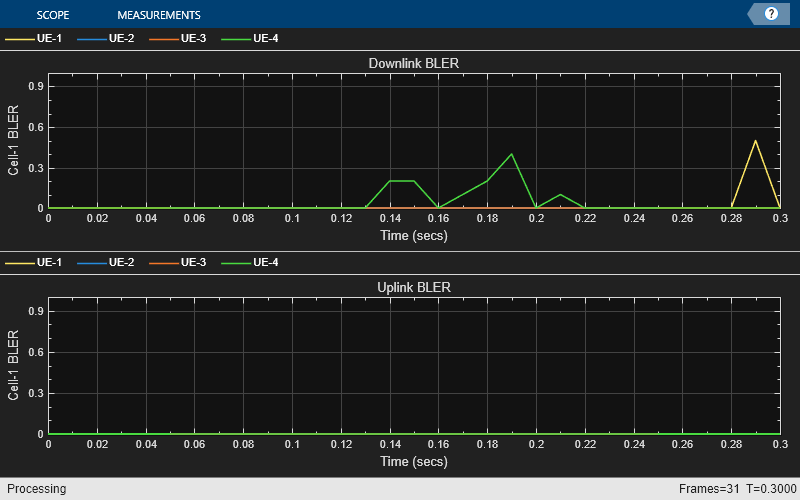

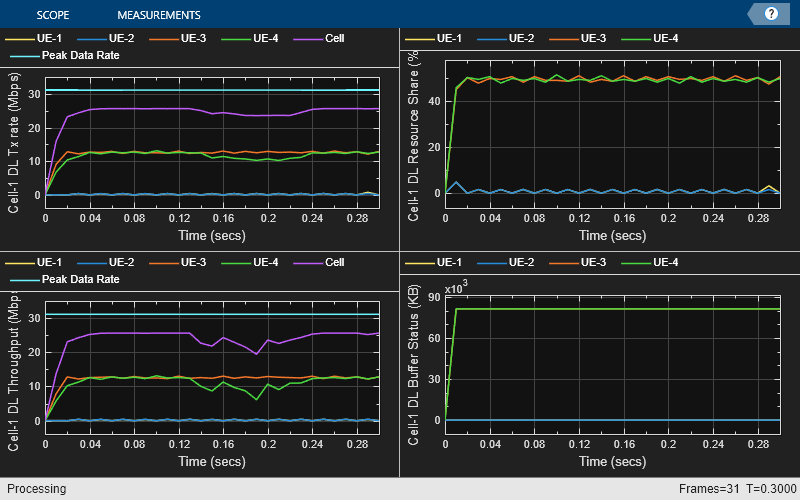

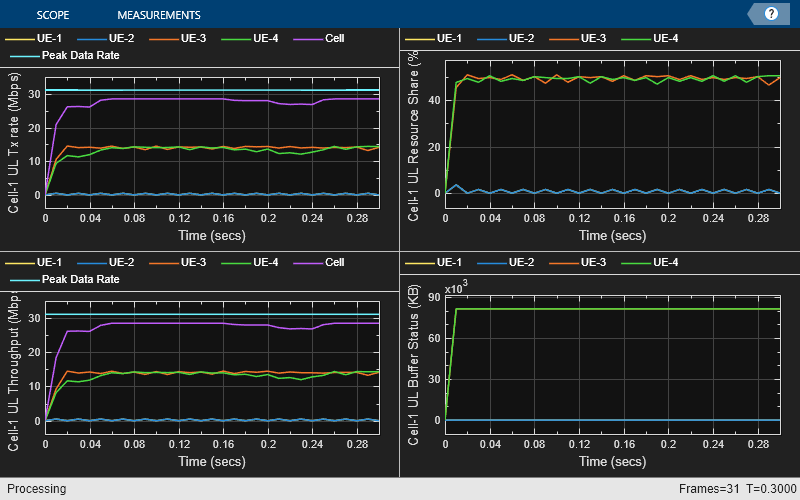

% Calculate the simulation duration (in seconds)
simulationTime = numFrameSimulation * 1e-2;
% Run the simulation
run(networkSimulator,simulationTime);

As the simulation runs, it updates the runtime visualizations, producing three main plots with multiple sub-plots. These figures provide detailed insights into various metrics, such as block error rate (BLER), transmit data rate, resource share, throughput, and buffer status for both the DL and UL directions of the cell. For more information about the runtime visualizations, see [Simulation Visualizations](docid:5g_ug#mw_73df19f5-3900-4a27-84a4-8d702b76679e).

## Results Analysis

Analyze the results of the simulation, focusing on the resource share plot, the statistics obtained for high-priority and low-priority UE nodes, and the achieved values of the system performance indicators.

### Resource Share Plot

When you observe the DL and UL resource share plots in the Simulation Results section, you can see that the scheduling strategy assigns resources to UE nodes based on their priority levels, giving high-priority UE nodes precedence over low-priority UE nodes. Every 20 milliseconds, spikes appear in the resource share plot, indicating the allocation of resources to high-priority UE nodes (UE-1 and UE-2) over low-priority UE nodes (UE-3 and UE-4). These spikes demonstrate that the scheduling strategy actively serves high-priority UE nodes as soon as they generate data and resets their buffer statuses to zero. In each slot, after serving high-priority UE nodes, the strategy equally distributes remaining resources among low-priority UE nodes. This periodic allocation pattern mirrors the traffic generation periodicity of high-priority UE nodes. Over time, the plot might show variability in resource allocation among UE nodes, reflecting the randomness of the channel and packet retransmissions.

### Custom Scheduler Statistics

Obtain custom scheduler statistics, specifically focusing on the total number of allotted RBs for high-priority UE nodes and low-priority UE nodes in both the DL and UL directions. Note that these statistics encompass only the allotted RBs for new transmissions. For more information about these statistics, see the `getAllottedRBCount` method of [`helperNRCustomSchedulingStrategy`](matlab:openExample('5g/NRPlugCustomSchedulerExample','supportingFile','helperNRCustomSchedulingStrategy')).

[statHighPriority,statLowPriority] = myScheduler.getAllottedRBCount();
fprintf("Allotted RBs for high-priority UE nodes in downlink and uplink directions respectively: %d, %d\n",statHighPriority(1),statHighPriority(2))

Allotted RBs for high-priority UE nodes in downlink and uplink directions respectively: 144, 128


In the example simulation, high-priority UE nodes generate a UL packet every 20 milliseconds. Over a simulation time of 30 frames, totaling 300 milliseconds, high-priority nodes generate 15 packets each. The scheduling strategy generates one UL grant per packet, with each grant consisting of 4 RBs. As a result, each high-priority UE node cumulatively receives allocation for 120 UL RBs. The same explanation applies to the DL direction. However, in the DL direction, high-priority UE nodes receive a higher total count of RBs compared to the UL direction, as UL scheduling occurs only after the buffer status report (BSR) reaches the gNB node.

To similarly evaluate the RB allocation for low-priority UE nodes, this code prints the total number of RBs allotted to low-priority UE nodes in both the DL and UL directions.

fprintf("Allotted RBs for low-priority UE nodes in downlink and uplink directions respectively: %d, %d\n",statLowPriority(1),statLowPriority(2))

Allotted RBs for low-priority UE nodes in downlink and uplink directions respectively: 7230, 7372


### Performance Indicators

Compare the achieved values of the system performance indicators with their theoretical peak values, which assume zero overhead. 

displayPerformanceIndicators(metricsVisualizer)

Peak UL throughput: 31.11 Mbps. Achieved cell UL throughput: 27.62 Mbps
Achieved UL throughput for each UE: [0.23         0.23         13.9        13.26]
Peak UL spectral efficiency: 6.22 bits/s/Hz. Achieved UL spectral efficiency for cell: 5.52 bits/s/Hz 
Block error rate for each UE in the UL direction: [0  0  0  0]

Peak DL throughput: 31.11 Mbps. Achieved cell DL throughput: 24.06 Mbps
Achieved DL throughput for each UE: [0.18         0.19        12.47        11.22]
Peak DL spectral efficiency: 6.22 bits/s/Hz. Achieved DL spectral efficiency for cell: 4.81 bits/s/Hz
Block error rate for each UE in the DL direction: [0.056           0           0        0.04]



The displayed performance indicators include the achieved data rate (UL and DL) at the PHY layer, spectral efficiency (UL and DL), and block error rate (UL and DL). This example calculates the theoretical peak value based on TR 37.910, which defines it as the total data bits a single mobile station can receive without errors, using the highest MCS, highest rank, and all available radio resources for data. For more information about peak data rate calculation, see [Simulation Visualizations](docid:5g_ug#mw_73df19f5-3900-4a27-84a4-8d702b76679e). Note that the achieved data rate is higher than the application data rate. This is because the fixed number of RBs allocated result in padding, which increases the number of transmission bytes.

## Simulation Logs

The example saves the simulation logs in a MAT file for post-simulation analysis, with conditional logging based on the value of `enableTraces`. For more information about the logged information, see the [NR Cell Performance Evaluation with MIMO](docid:5g_ug#mw_5b092ec2-40de-4aff-a2ad-dcef2ffe8654) example. 

if enableTraces
    simulationLogs = cell(1,1);
    if gNB.DuplexMode == "FDD"
        logInfo = struct(DLTimeStepLogs=[],ULTimeStepLogs=[], ...
            SchedulingAssignmentLogs=[],PhyReceptionLogs=[]);
        [logInfo.DLTimeStepLogs,logInfo.ULTimeStepLogs] = getSchedulingLogs(simSchedulingLogger);
    else % TDD
        logInfo = struct(TimeStepLogs=[],SchedulingAssignmentLogs=[],PhyReceptionLogs=[]);
        logInfo.TimeStepLogs = getSchedulingLogs(simSchedulingLogger);
    end
    % Get the scheduling assignments log
    logInfo.SchedulingAssignmentLogs = getGrantLogs(simSchedulingLogger);
    % Get the PHY reception logs
    logInfo.PhyReceptionLogs = getReceptionLogs(simPhyLogger);
    % Save simulation logs in a MAT file
    simulationLogs{1} = logInfo;
    save(simulationLogFile,"simulationLogs")
end

## Further Exploration

This example demonstrated how to write and add a custom scheduler into a 5G system-level simulation. It considers four UE nodes distributed within a 250-meter distance from the gNB node. Try running the example for different numbers of UE nodes. 

For instance, this plot illustrates the UL throughput using the implemented custom scheduling strategy for 200 UE nodes distributed within a 100-meter distance from the gNB. The first 80 UEs have high-priority, while the remaining UEs are low-priority. The SRS transmission periodicity of all the UE nodes is set to 80 slots. All other configurations remain the same as in this example script.

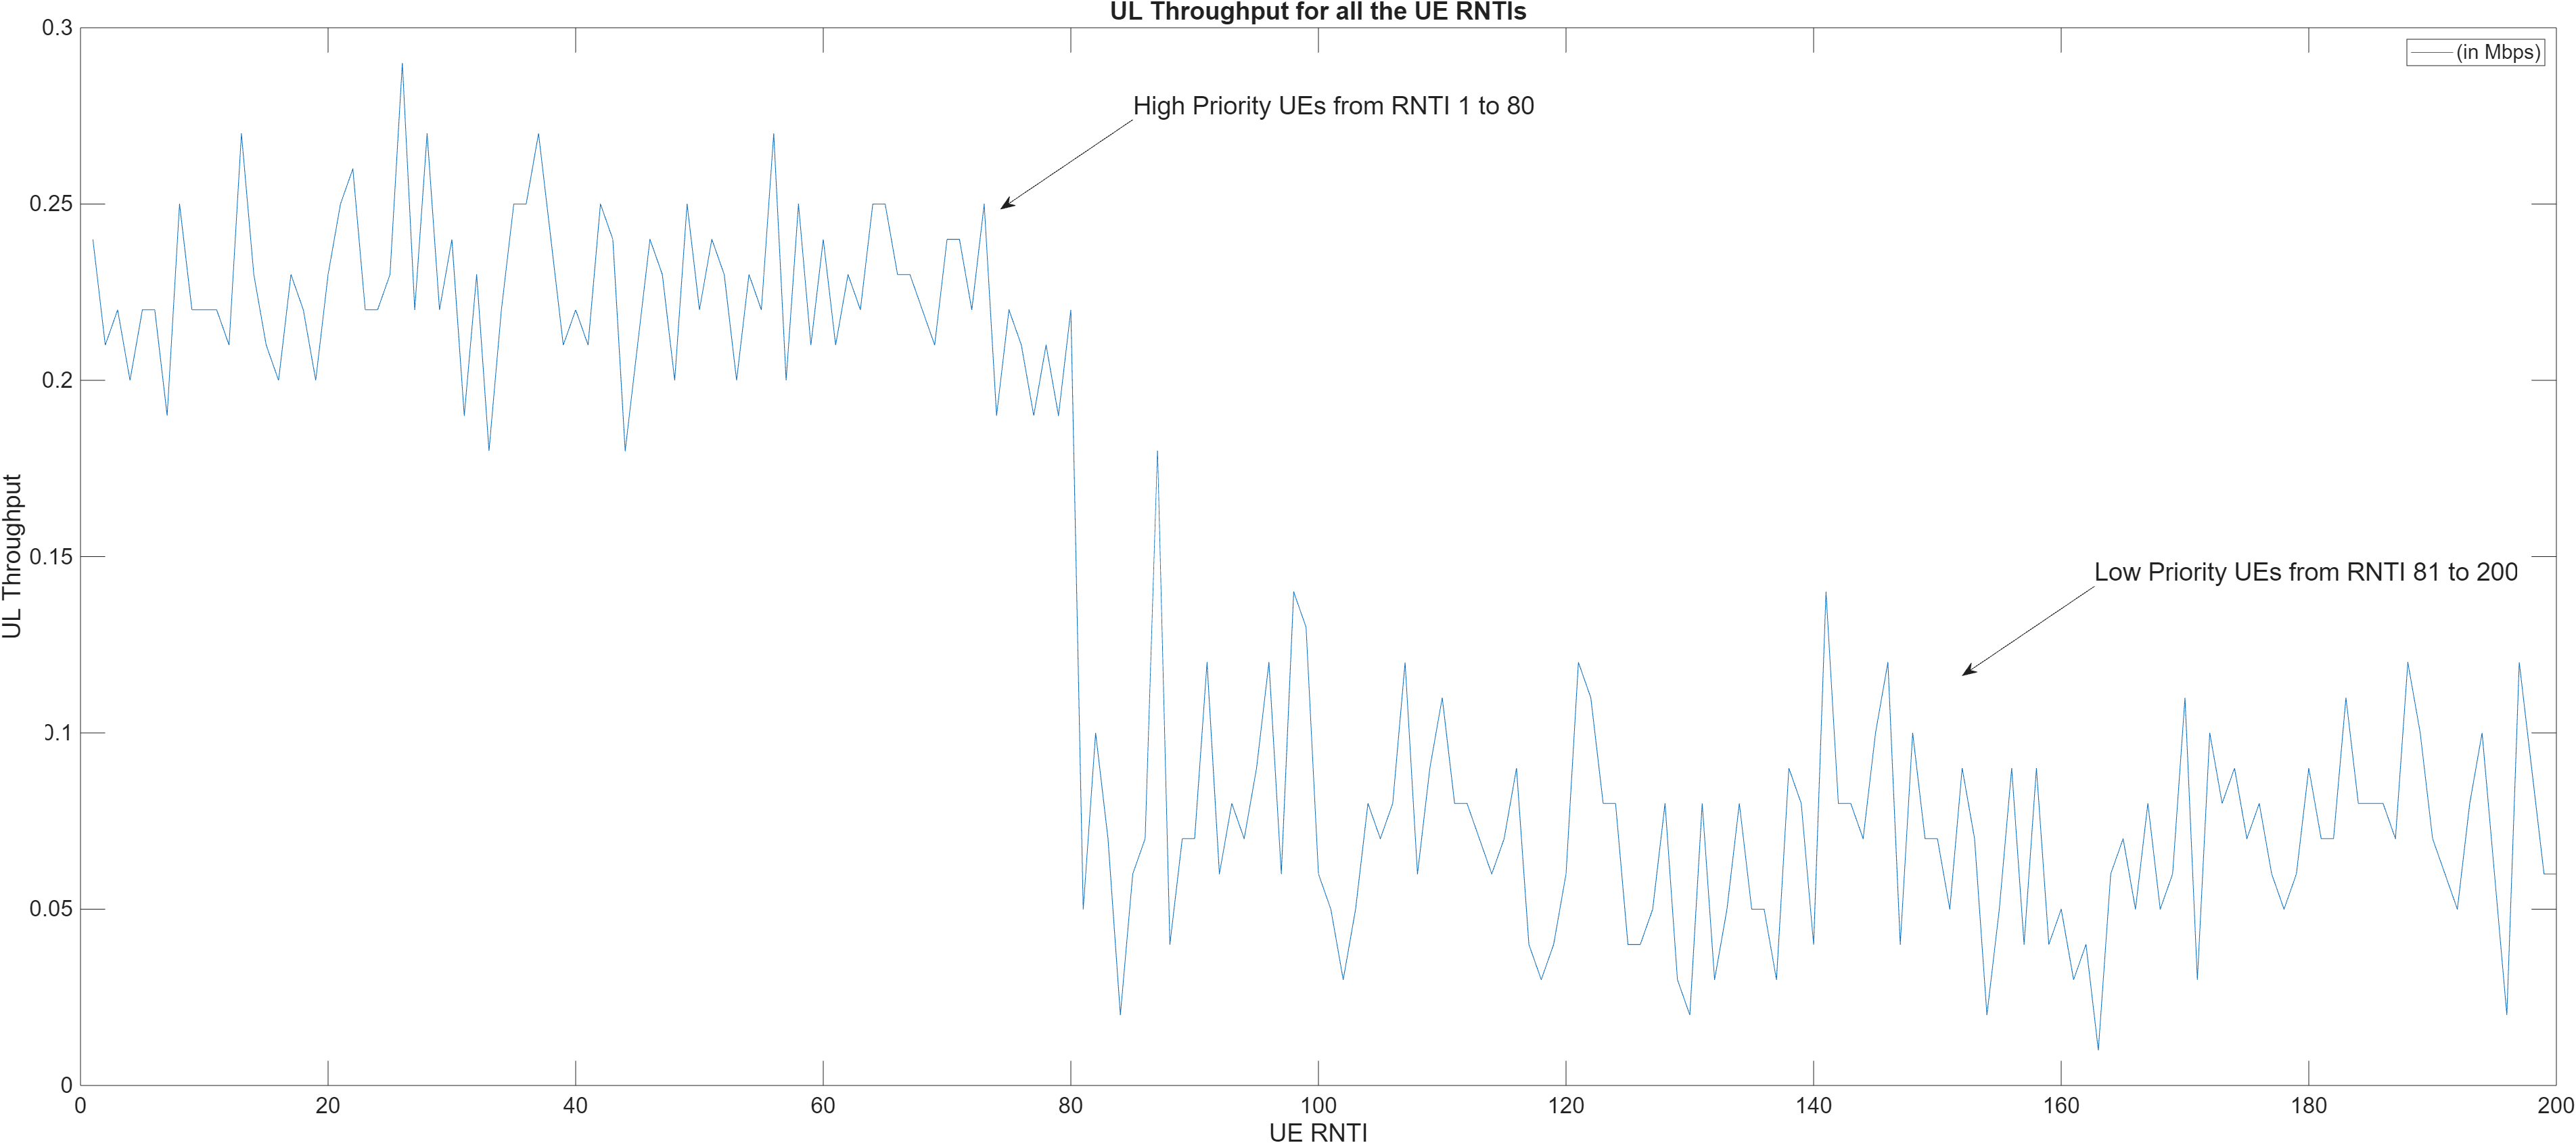

Notably, this plot demonstrates that high-priority UE nodes receive precedence over low-priority UE nodes. Consequently, the first 80 UE nodes achieve higher throughput because they receive grants before the low-priority UE nodes. Once their buffer status reaches zero, the scheduler allocates grants to the low-priority UE nodes. This results in lower throughput for the low-priority UE nodes, as they receive fewer grants overall. The same trend occurs in the DL direction.

To explore further, you can modify the parameters of the scheduling strategy in this example or implement your own custom scheduling strategy to evaluate network performance.

## Appendix

The example uses these helper files:

- [`helperNRMetricsVisualizer`](matlab:openExample('5g/NRPlugCustomSchedulerExample','supportingFile','helperNRMetricsVisualizer'))— Implements metrics visualization functionality

- [`helperNRSchedulingLogger`](matlab:openExample('5g/NRPlugCustomSchedulerExample','supportingFile','helperNRSchedulingLogger'))—  Implements scheduling information logging functionality

- [`helperNRPhyLogger`](matlab:openExample('5g/NRPlugCustomSchedulerExample','supportingFile','helperNRPhyLogger'))— Implements PHY packet reception information logging functionality

- [`h38901Channel`](matlab:openExample('5g/NRPlugCustomSchedulerExample','supportingFile','h38901Channel'))— Implements the 3GPP TR 38.901 channel model

- [`hArrayGeometry`](matlab:openExample('5g/NRPlugCustomSchedulerExample','supportingFile','hArrayGeometry'))— Configures antenna array geometry for CDL channel model

- [`helperNRCustomSchedulingStrategy`](matlab:openExample('5g/NRPlugCustomSchedulerExample','supportingFile','helperNRCustomSchedulingStrategy'))— Implements custom scheduling strategy

*Copyright 2021-2024 The MathWorks, Inc.*